# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 3-a. 샘플링과 데이터 홀드의 이해**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2022b 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : Simulink 상에서의 샘플러 구현

Topic 1에서는 다음의 연속 시간 정현파 신호


$$u(t)=3 \sin (2\pi t)$$


를 샘플링한 이산 시간 신호


$$u^d(k)=3\sin (2\pi kT)$$


를 만들어내는 샘플러를 Simulink 환경에서 구현해보고자 합니다. 편의상 샘플링 주기 $T$를 $0.2~{\rm sec}$로 고정합시다.

T = 0.2;            % Sampling period

이제 위의 목적을 위해 미리 작성된 아래의 Simulink 파일을 살펴봅시다. 

open('sim_topic1.slx');

Simulink 파일의 내부는 다음 그림과 같은 블록들이 작성되어 있습니다.

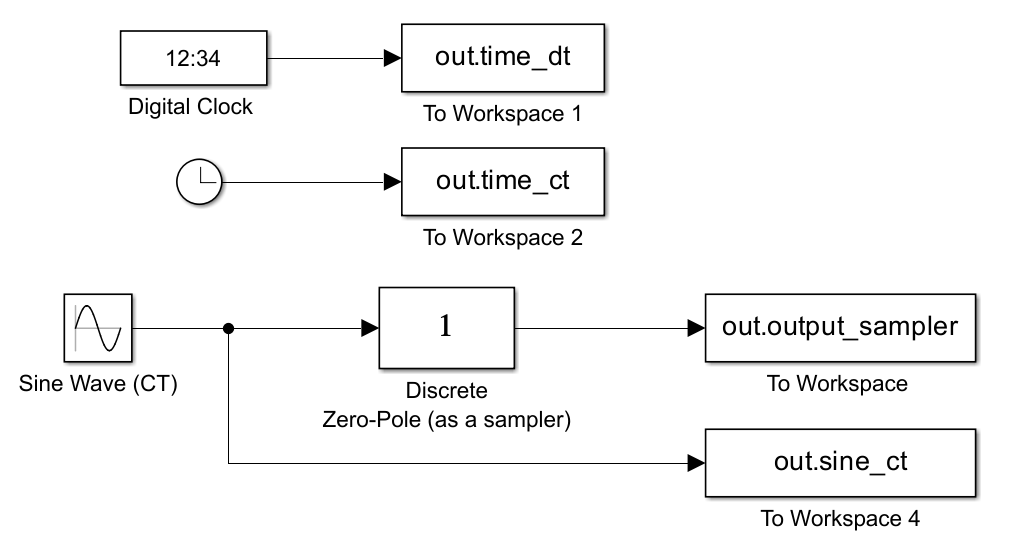

여기서 Sine Wave (CT) 블록은 연속 시간의 정현파 신호 $u(t)$를 생성하며, 더블 클릭하여 진폭, 주파수 등을 조정할 수 있습니다. 

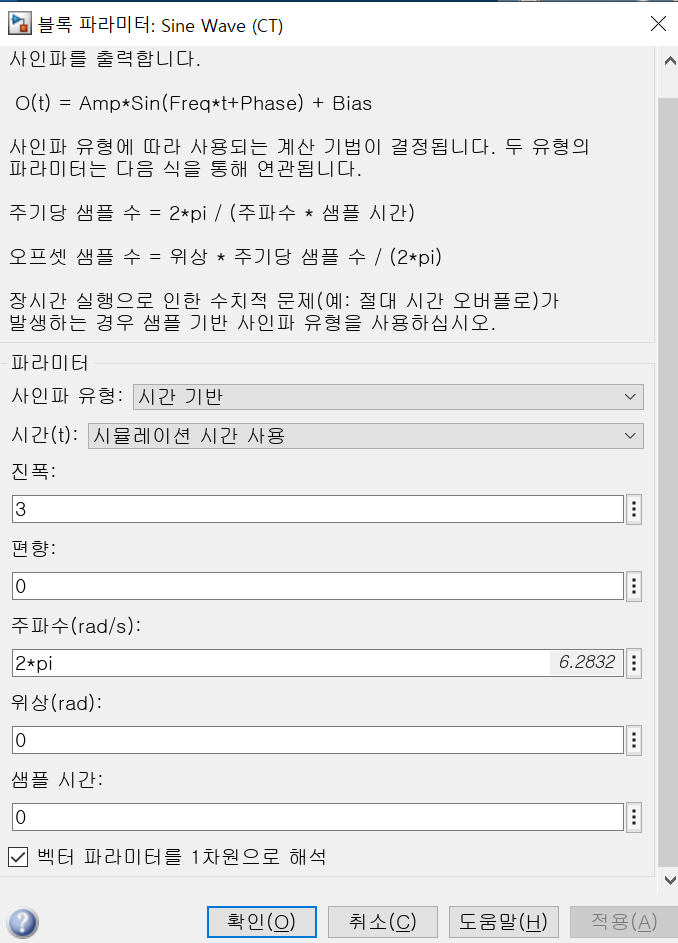

(여기서 하단의 "샘플 시간"에 샘플링 주기 $T
$를 입력하면 이산 시간의 정현파를 만드는 블록으로 변경할 수도 있습니다.)

**Simulink는 별도의 샘플러 블록을 제공하지 않기 때문에, Simulink 환경에서 샘플러를 구현하기 위해서는 약간의 트릭이 필요합니다.**

다양한 방법이 있는데, 이 파일에서는 [라이브러리 브라우저]-[Simulink]-[Discrete] 카테고리에 있는 **"Discrete Zero-Pole" 블록을 활용하고자 합니다. **

원래  "Discrete Zero-Pole" 블록은 이산 시간 전달함수를 구현하는 블록인데, 특히 아래와 같이 영점(zero)과 극점(pole)이 없도록 지정하면 이산 시간 전달함수 $1$을 나타내는 블록이 만들어집니다. 

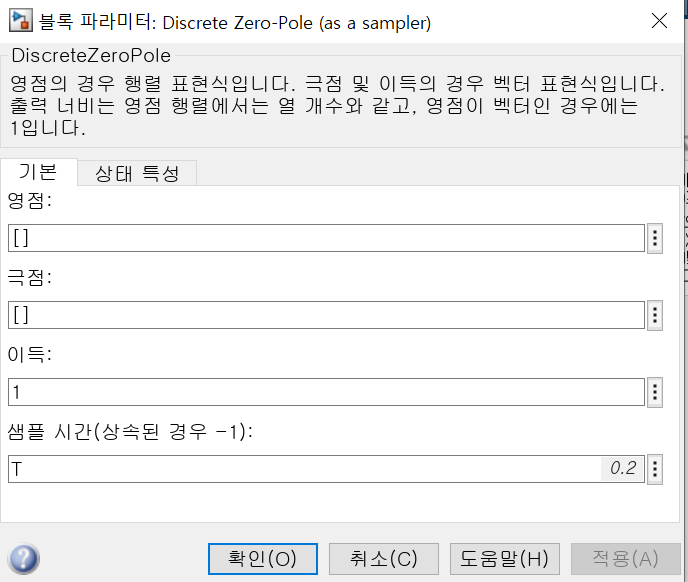

이 블록은 결과적으로는 샘플러의 역할을 하게 되며, 이 블록에 연속 시간 신호를 입력하면 샘플링된 이산 시간 신호인 $u^d(k)=u(kT)$가 출력됩니다. 

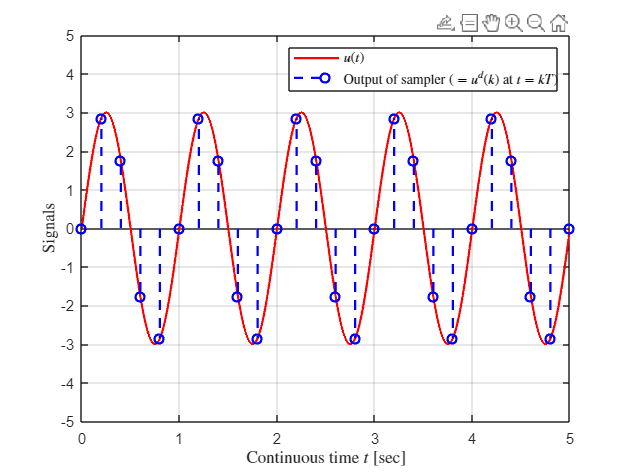

T_sim = 5;                  % Simulation의 종료 시간
dt_sim = 0.001;             % Simulation의 sampling period

sim('sim_topic1.slx');
simout = ans;
time_dt_sim1 = simout.time_dt;
time_ct_sim1 = simout.time_ct;
output_sampler_sim1 = simout.output_sampler;
sine_ct_sim1 = simout.sine_ct;

figure();
plot(time_ct_sim1,sine_ct_sim1,'r','LineWidth',1.5);
hold on;
stem(time_dt_sim1,output_sampler_sim1,'--b','LineWidth',1.5);
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Signals','Interpreter','latex');
xlim([0 T_sim]); 
ylim([-5 5]);
legend('Input of sampler $u(t)$','Output of sampler ($=u^d(k)$ at $t=kT$)','Interpreter','latex','Location','northeast'); 

**참고** : 위의 코드에서 dt_sim은 Similink 계산이 수행되는 샘플링 주기를 의미하며(즉, Simulink는 dt_sim 시간 마다 Simulink 파일의 블록들의 내용을 계산하고 업데이트합니다), 이 값은 Simulink 상단의 [모델링]-[모델 설정]-[솔버]-[솔버 세부 정보]-[고정 스텝 크기(기본 샘플 시간)]에 사용됩니다. 

(정교한 시뮬레이션을 위해 고정 스텝 유형의 솔버를 사용하며, 처음 Simulink를 접하는 경우라면 위의 내용까지 자세히 알 필요는 없습니다.)

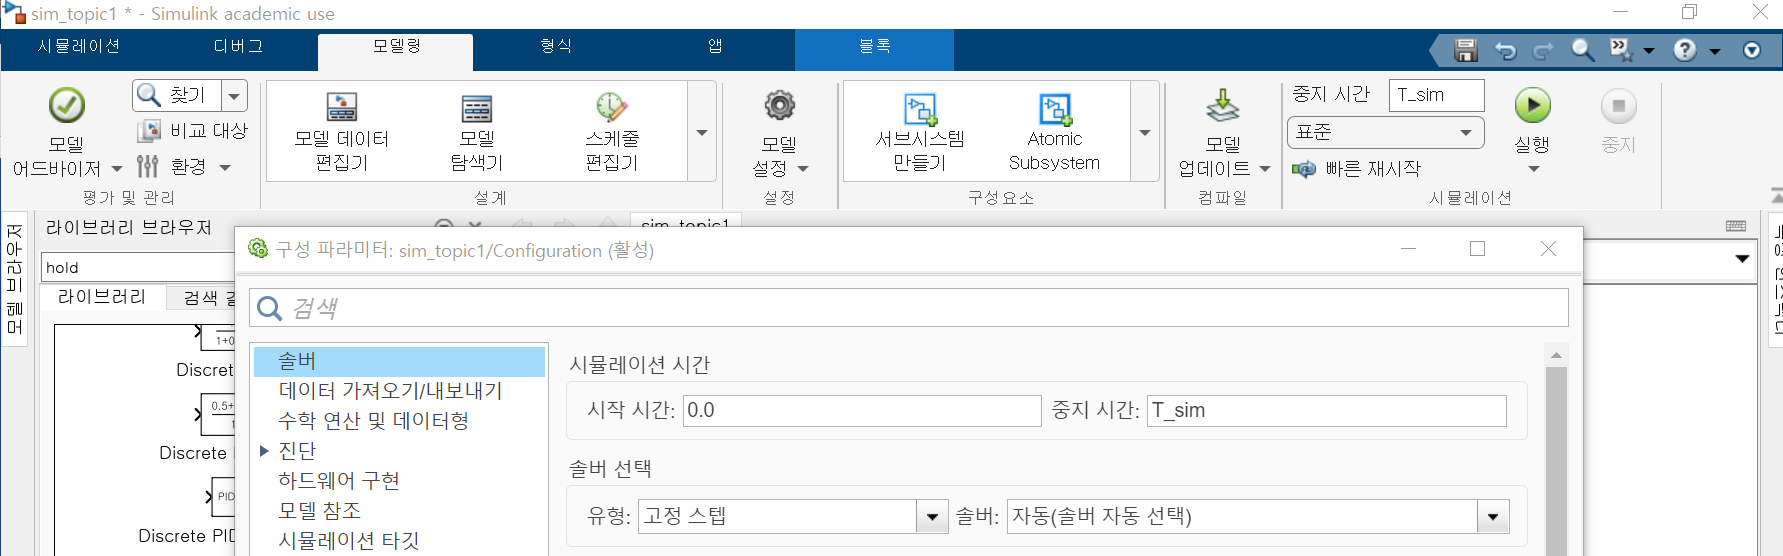

### Topic 2 : Simulink 상에서 0차 홀드를 통한 이산 시간 신호의 연속화

Topic 2에서는 이산 시간 신호를 연속 시간 신호로 바꾸는 0차 홀드(zero-order hold)를 Simulink 상에서 구현해보도록 하겠습니다. 

미리 작성된 아래의 Simulink 파일을 살펴봅시다.

open('sim_topic2.slx');

파일을 열어보면 아래의 블록 다이어그램을 확인할 수 있습니다. 여기서 **Zero-order Hold 블록이 0차 홀드의 역할을 하며, [라이브러리 브라우저]-[Simulink] 카테고리에서 찾을 수 있습니다.**

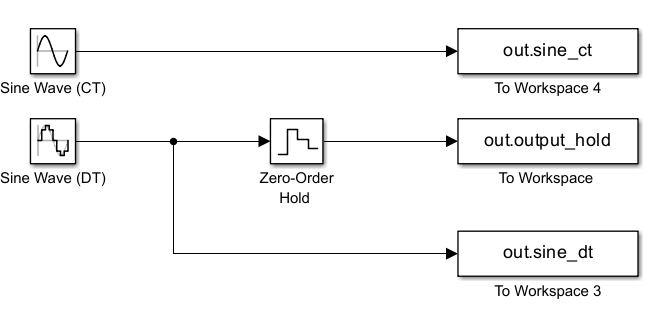

한편 이산 시간의 정현파 신호를 만들어내는 Sine Wave 블록은, 앞서 설명한 대로 기존 Sine Wave 블록에서 "샘플 시간"을 샘플링 주기 $T$로 변경하여 얻습니다.

이제 위의 블록을 시뮬레이션하고 결과를 살펴보면 다음과 같습니다.

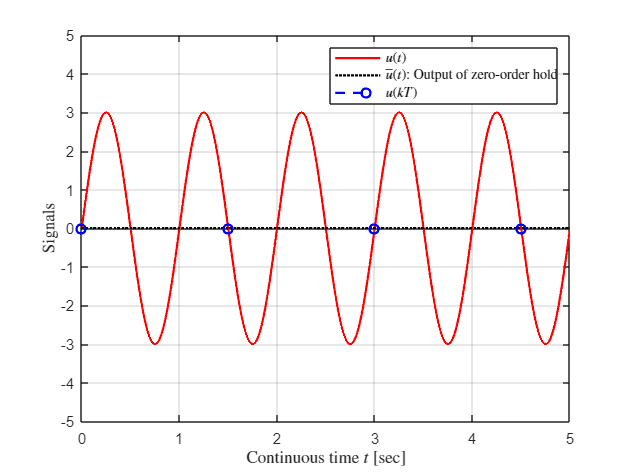

sim('sim_topic2.slx');
simout = ans;
time_dt_sim2 = simout.time_dt;
time_ct_sim2 = simout.time_ct;
output_hold_sim2 = simout.output_hold;
sine_dt_sim2 = simout.sine_dt;
sine_ct_sim2 = simout.sine_ct;

figure();
plot(time_ct_sim2,sine_ct_sim2,'r','LineWidth',1.5);
hold on;
plot(time_ct_sim2,output_hold_sim2,':k','LineWidth',1.5);
hold on;
stem(time_dt_sim2,sine_dt_sim2,'--b','LineWidth',1.5);
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Signals','Interpreter','latex');
xlim([0 T_sim]); 
ylim([-5 5]);
legend('$u(t)$','$\overline{u}(t)$: Output of zero-order hold', '$u(kT)$','Interpreter','latex','Location','northeast'); 

0차 홀드의 결과 신호는 $kT \leq t <(k+1)T$ 시간 동안 $u^d(k)$의 값을 유지하는 모습을 보이며, 따라서 필연적으로 기존의 연속 시간 신호인 $u(t)$와 정확히 같지는 않습니다. 

### Topic 3 : 샘플링 주기에 따른 0차 홀드 결과의 변화. 

Topic 3에서는 for 문을 이용하여  샘플링 주기 $T$를 바꿔가면서 Topic 2의 시뮬레이션을 반복적으로 수행하고, 그 결과를 비교해봅니다.

자연스럽게도 샘플링 주기 $T$가 짧아짐에 따라 0차 홀드의 결과인 $\overline{u}(t)$가 기존 신호인 $u(t)$를 좀 더 정교하게 구현해냄을 확인할 수 있습니다.

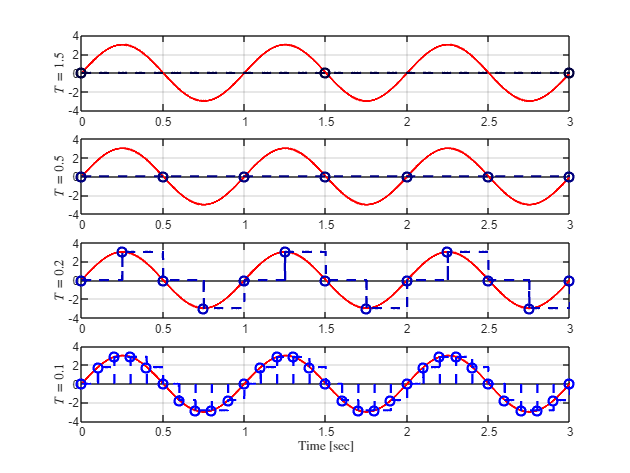

listT = {1.5, 0.5, 0.25, 0.1};

for idx = 1:length(listT)
    T = listT{idx};
    sim('sim_topic2.slx');

    simout = ans;
    time_dt_sim3{idx} = simout.time_dt;
    time_ct_sim3{idx}= simout.time_ct;
    output_hold_sim3{idx} = simout.output_hold;
    sine_dt_sim3{idx} = simout.sine_dt;
    sine_ct_sim3{idx} = simout.sine_ct;
end

figure();
hold on;
for idx = 1:length(listT)
    subplot(4,1,idx)
    plot(time_ct_sim3{1},sine_ct_sim3{1},'r','LineWidth',1.5);
    hold on;
    plot(time_ct_sim3{idx},output_hold_sim3{idx},'--','Color',(1/4)*[0 0 1]*idx,'LineWidth',1.5);
    hold on;
    stem(time_dt_sim3{idx},sine_dt_sim3{idx},'--','Color',(1/4)*[0 0 1]*idx,'LineWidth',1.5);
    grid on;
    xlim([0 3]);
    ylim([-4 4]);
    ylabel(strcat('$T=$',sprintf('%.1f',listT{idx})), 'Interpreter','latex');
end
xlabel('Time [sec]','Interpreter','latex');

흥미로운 점은, $T=1.5$인 경우와 $T=0.5$인 경우는 0차 홀드의 결과인 $\overline{u}(t)$가 언제나 $0$이라는 점입니다. 

이는 샘플링에 비해 상대적으로 너무 빠른 연속 시간 신호는 온전히 재복원해내기 어렵다는, Shannon의 샘플링 이론과 정확히 같은 방향의 결과입니다.